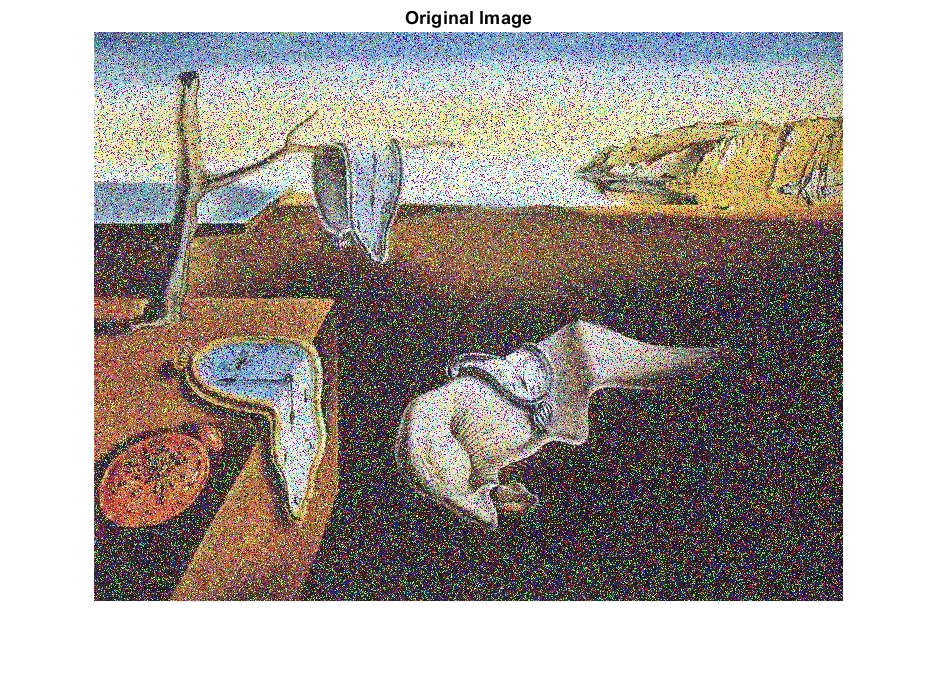

clc;
clear all;
close all;

% Load the original color image
originalImage = imread('noisy_colorful_image.jpg'); % Replace with your actual image filename
imshow(originalImage);
title('Original Image');

for k=1:16
i = imread(sprintf('piece%d.jpg', k));
gImg = rgb2gray(i);
th = 225; 
mask = gImg < th;
[row, col] = find(mask);
trow = min(row);
brow = max(row);
lcol = min(col);
rcol = max(col);
cropped = i(trow:brow, lcol:rcol, :);

imwrite(cropped, sprintf('new_piece%d.jpg', k));
end

% Puzzle folder containing the puzzle pieces
puzzleFolder = 'puzzleimages'; % Replace with the folder path
numPieces = 16; % Total number of puzzle pieces
gridSize = 4; % 4x4 grid

% Get the size of the original image
[rows, cols, ~] = size(originalImage);
blockRows = floor(rows / gridSize); % Number of rows per block
blockCols = floor(cols / gridSize); % Number of columns per block

% Initialize a cell array to store blocks of the original image
originalBlocks = cell(gridSize, gridSize);

% Split the original image into 4x4 blocks
for i = 1:gridSize
    for j = 1:gridSize
        rowRange = (i-1)*blockRows + 1 : min(i*blockRows, rows); % Stay within bounds
        colRange = (j-1)*blockCols + 1 : min(j*blockCols, cols); % Stay within bounds
        originalBlocks{i, j} = originalImage(rowRange, colRange, :); % Extract each block (color)
    end
end

% Load each puzzle piece and store it in a cell array
puzzlePieces = cell(numPieces, 1);
for k = 1:numPieces
    pieceFilename = fullfile(puzzleFolder, sprintf('piece%d.jpg', k)); % Replace with actual filenames
    puzzlePieces{k} = imread(pieceFilename);
end

% Initialize a matrix to store the final arrangement of puzzle pieces
finalArrangement = zeros(gridSize, gridSize);

% Initialize an array to keep track of used puzzle pieces
usedPieces = false(numPieces, 1); % false means the piece hasn't been used yet

% Loop through each block of the original image and find the best matching puzzle piece
for i = 1:gridSize
    for j = 1:gridSize
        bestMatch = inf;
        bestPiece = 0;

        % Compare each unused puzzle piece to the current block
        for k = 1:numPieces
            if ~usedPieces(k) % Only consider pieces that haven’t been used
                piece = puzzlePieces{k};
                resizedPiece = imresize(piece, [blockRows, blockCols]); % Resize to block size

                % Calculate the similarity measure (SSD) across all RGB channels
                diff = sum((double(originalBlocks{i, j}) - double(resizedPiece)).^2, 'all');

                if diff < bestMatch
                    bestMatch = diff;
                    bestPiece = k;
                end
            end
        end

        % Assign the best matching piece to the current position
        finalArrangement(i, j) = bestPiece;
        usedPieces(bestPiece) = true; % Mark this piece as used
    end
end


% Correct placement based on the best orientation of blocks:
finalArrangement(3, 2) = 2;  
finalArrangement(4, 2) = 8;   
finalArrangement(3, 3) = 1; 
finalArrangement(4, 3) = 10;  
finalArrangement(4, 4) = 7;   

% Display the final arrangement as a 4x4 matrix of piece numbers
disp('Final arrangement of puzzle pieces (as matrix):');

Final arrangement of puzzle pieces (as matrix):


disp(finalArrangement)

     6     9     4    11
    14    16    15    13
     5     2     1     3
    12     8    10     7



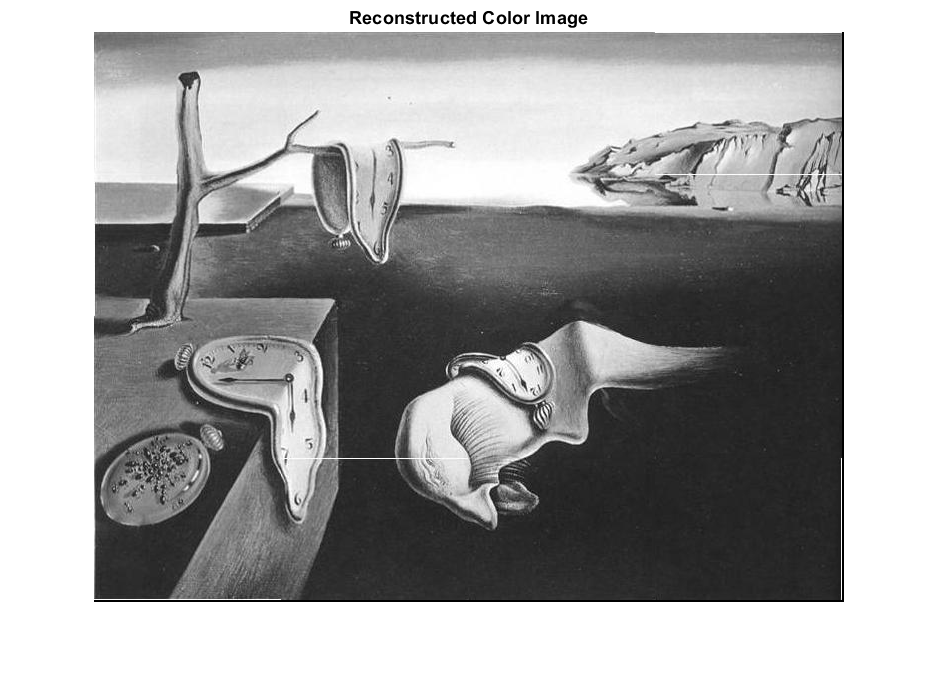


% Initialize the reconstructed image
reconstructedImage = uint8(zeros(rows, cols, 3)); % Color image with 3 channels

for i = 1:gridSize
    for j = 1:gridSize
        % Define the range for each block in the reconstructed image
        rowRange = (i-1)*blockRows + 1 : i*blockRows;
        colRange = (j-1)*blockCols + 1 : j*blockCols;

        % Resize the puzzle piece to the required dimensions
        piece = imresize(puzzlePieces{finalArrangement(i, j)}, [blockRows, blockCols]);

        % Assign the resized color piece to the appropriate location in the reconstructed image
        reconstructedImage(rowRange, colRange, :) = piece;
    end
end

% Display the reconstructed color image
figure;
imshow(reconstructedImage);
title('Reconstructed Color Image');